dataset_dir = 'dataset\';

dataset = imageDatastore(dataset_dir,   'IncludeSubfolders', true, 'LabelSource', 'foldernames');
BanyakChar = countEachLabel(dataset)

BanyakChar = 36×2 table
    Label    Count
    _____    _____

    0        2    
    1        1    
    2        1    
    3        1    
    4        1    
    5        1    
    6        1    
    7        1    
    8        1    
    9        1    
    A        1    
    B        1    
    C        1    
    D        1    
    E        1    
    F        1    
    G        1    
    H        1    
    I        1    
    J        1    
    K        1    
    L        1    
    M        1    
    N        1    
    O        1    
    P        1    
    Q        1    
    R        1    
    S        1    
    T        1    
    U        1    
    V        1    
    W        1    
    X        1    
    Y        1    
    Z        1    


BanyakImg = numel(dataset.Files);

CharImg = string(dataset.Labels);
Char = zeros(numel(double(table2array(BanyakChar(:,1)))),BanyakImg);
for i = 1:BanyakImg
    dataImg = readimage(dataset, i);
    DatasetImg{i} = dataImg;
    if CharImg(i)== "0"
        Char(1,i) = 1;
    elseif CharImg(i) == "1"
        Char(2,i) = 1;
    elseif CharImg(i) == "2"
        Char(3,i) = 1;
    elseif CharImg(i) == "3"
        Char(4,i) = 1;
    elseif CharImg(i) == "4"
        Char(5,i) = 1;
    elseif CharImg(i) == "5"
        Char(6,i) = 1;
    elseif CharImg(i) == "6"
        Char(7,i) = 1;
    elseif CharImg(i) == "7"
        Char(8,i) = 1;
    elseif CharImg(i) == "8"
        Char(9,i) = 1;
    elseif CharImg(i) == "9"
        Char(10,i) = 1;
    elseif CharImg(i) == "A"
        Char(11,i) = 1;
    elseif CharImg(i) == "B"
        Char(12,i) = 1;
    elseif CharImg(i) == "C"
        Char(13,i) = 1;
    elseif CharImg(i) == "D"
        Char(14,i) = 1;
    elseif CharImg(i) == "E"
        Char(15,i) = 1;
    elseif CharImg(i) == "F"
        Char(16,i) = 1;
    elseif CharImg(i) == "G"
        Char(17,i) = 1;
    elseif CharImg(i) == "H"
        Char(18,i) = 1;
    elseif CharImg(i) == "I"
        Char(19,i) = 1;
    elseif CharImg(i) == "J"
        Char(20,i) = 1;
    elseif CharImg(i) == "K"
        Char(21,i) = 1;
    elseif CharImg(i) == "L"
        Char(22,i) = 1;
    elseif CharImg(i) == "M"
        Char(23,i) = 1;
    elseif CharImg(i) == "N"
        Char(24,i) = 1;
    elseif CharImg(i) == "O"
        Char(25,i) = 1;
    elseif CharImg(i) == "P"
        Char(26,i) = 1;
    elseif CharImg(i) == "Q"
        Char(27,i) = 1;
    elseif CharImg(i) == "R"
        Char(28,i) = 1;
    elseif CharImg(i) == "S"
        Char(29,i) = 1;
    elseif CharImg(i) == "T"
        Char(30,i) = 1;
    elseif CharImg(i) == "U"
        Char(31,i) = 1;
    elseif CharImg(i) == "V"
        Char(32,i) = 1;
    elseif CharImg(i) == "W"
        Char(33,i) = 1;
    elseif CharImg(i) == "X"
        Char(34,i) = 1;
    elseif CharImg(i) == "Y"
        Char(35,i) = 1;
    elseif CharImg(i) == "Z"
        Char(36,i) = 1;
    end
    %c = dec2bin(a(i), 8);
    %Limg(:,i) = c(:) - '0';
end

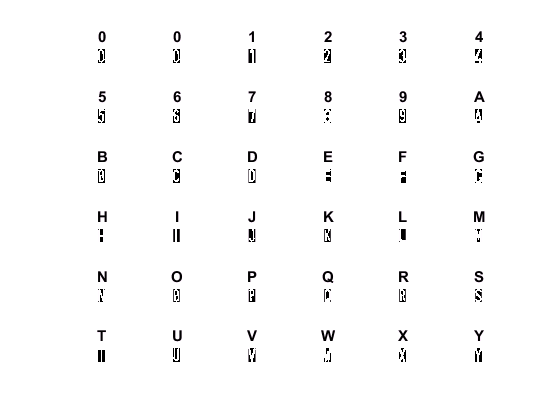

figure                                          % initialize figure                                 % set to grayscale
for i = 1:36                                    % preview first 36 samples
    subplot(6,6,i)                              % plot them in 6 x 6 grid
    digit = double(DatasetImg{i});     % row = 28 x 28 image
    imshow(digit)                              % show the image
    title(CharImg(i))                   % show the label
end

%edu_createnn(DatasetImg,Char);

rng('default')

hiddenSize1 = 100;

autoenc1 = trainAutoencoder(DatasetImg,hiddenSize1, ...
    'MaxEpochs',400, ...
    'L2WeightRegularization',0.004, ...
    'SparsityRegularization',4, ...
    'SparsityProportion',0.15, ...
    'ScaleData', false);

view(autoenc1)

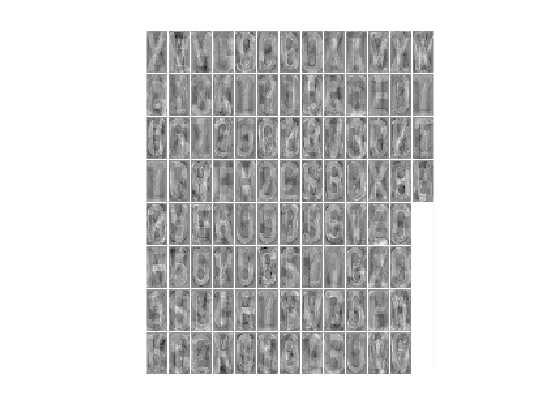

figure()
plotWeights(autoenc1);

feat1 = encode(autoenc1,DatasetImg);

hiddenSize2 = 50;
autoenc2 = trainAutoencoder(feat1,hiddenSize2, ...
    'MaxEpochs',100, ...
    'L2WeightRegularization',0.002, ...
    'SparsityRegularization',4, ...
    'SparsityProportion',0.1, ...
    'ScaleData', false);

view(autoenc2)

feat2 = encode(autoenc2,feat1);

softnet = trainSoftmaxLayer(feat2,Char,'MaxEpochs',400);

view(softnet)

view(autoenc1)
view(autoenc2)
view(softnet)

deepnet = stack(autoenc1,autoenc2,softnet);

view(deepnet)

% Get the number of pixels in each image
imageWidth = 16;
imageHeight = 32;
inputSize = imageWidth*imageHeight;

% Turn the training images into vectors and put them in a matrix
xTrain = zeros(inputSize,numel(DatasetImg));
for i = 1:numel(DatasetImg)
    xTrain(:,i) = DatasetImg{i}(:);
end

% Perform fine tuning
deepnet = train(deepnet,xTrain,Char);

sample_dir = 'datauji\';
Sample = imageDatastore(sample_dir,   'IncludeSubfolders', true, 'LabelSource', 'foldernames'); 
Banyaksample = numel(Sample.Files);
for i = 1:Banyaksample
    SamImg = readimage(Sample, i);
    SampleImg{i} = SamImg;
end

xTest = zeros(inputSize,numel(SampleImg));
for i = 1:numel(SampleImg)
    xTest(:,i) = SampleImg{i}(:);
end

y = deepnet(xTest);
hasil=round(y)

hasil =      0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0


for i=1:numel(hasil(1,:))
    if hasil(1,i) == 1
        hasilakhir(:,i) = "0"
    elseif hasil(2,i) == 1
        hasilakhir(:,i) = "1"
    elseif hasil(3,i) == 1
        hasilakhir(:,i) = "2"
    elseif hasil(4,i) == 1
        hasilakhir(:,i) = "3"
    elseif hasil(5,i) == 1
        hasilakhir(:,i) = "4"
    elseif hasil(6,i) == 1
        hasilakhir(:,i) = "5"
    elseif hasil(7,i) == 1
        hasilakhir(:,i) = "6"
    elseif hasil(8,i) == 1
        hasilakhir(:,i) = "7"
    elseif hasil(9,i) == 1
        hasilakhir(:,i) = "8"
    elseif hasil(10,i) == 1
        hasilakhir(:,i) = "9"
    elseif hasil(11,i) == 1
        hasilakhir(:,i) = "A"
    elseif hasil(12,i) == 1
        hasilakhir(:,i) = "B"
    elseif hasil(13,i) == 1
        hasilakhir(:,i) = "C"
    elseif hasil(14,i) == 1
        hasilakhir(:,i) = "D"
    elseif hasil(15,i) == 1
        hasilakhir(:,i) = "E"
    elseif hasil(16,i) == 1
        hasilakhir(:,i) = "F"
    elseif hasil(17,i) == 1
        hasilakhir(:,i) = "G"
    elseif hasil(18,i) == 1
        hasilakhir(:,i) = "H"
    elseif hasil(19,i) == 1
        hasilakhir(:,i) = "I"
    elseif hasil(20,i) == 1
        hasilakhir(:,i) = "J"
    elseif hasil(21,i) == 1
        hasilakhir(:,i) = "K"
    elseif hasil(22,i) == 1
        hasilakhir(:,i) = "L"
    elseif hasil(23,i) == 1
        hasilakhir(:,i) = "M"
    elseif hasil(24,i) == 1
        hasilakhir(:,i) = "N"
    elseif hasil(25,i) == 1
        hasilakhir(:,i) = "O"
    elseif hasil(26,i) == 1
        hasilakhir(:,i) = "P"
    elseif hasil(27,i) == 1
        hasilakhir(:,i) = "Q"
    elseif hasil(28,i) == 1
        hasilakhir(:,i) = "R"
    elseif hasil(29,i) == 1
        hasilakhir(:,i) = "S"
    elseif hasil(30,i) == 1
        hasilakhir(:,i) = "T"
    elseif hasil(31,i) == 1
        hasilakhir(:,i) = "U"
    elseif hasil(32,i) == 1
        hasilakhir(:,i) = "V"
    elseif hasil(33,i) == 1
        hasilakhir(:,i) = "W"
    elseif hasil(34,i) == 1
        hasilakhir(:,i) = "X"
    elseif hasil(35,i) == 1
        hasilakhir(:,i) = "Y"
    elseif hasil(36,i) == 1
        hasilakhir(:,i) = "Z"
    end
end

hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


hasilakhir = 1×11 string array
    "D"    "V"    <missing>    <missing>    "K"    "2"    "9"    "7"    "1"    "O"    "P"


A = rmmissing(hasilakhir);
C = cellstr(A);
Plat_kendaraan = sprintf('%s' ,C{:});
%j = join(hasil);
%huruf = bin2dec(hasil

%outputs = deepnet(xTest);
%errors = gsubtract(targets,outputs);

Error using bsxfun
Non-singleton dimensions of the two input arrays must match each other.

Error in gsubtract (line 22)
  c = bsxfun(@minus,a,b);

%performance = perform(net,targets,outputs)

%ypr = predict(deepnet,xTest)

Error using predict (line 84)
No valid system or dataset was specified.